# De-Trend-Before-FFT filtering

Trends kinda bork the appearance of the signal's power spectrum, so de-trending it first might make it easier to decide on a filter.

The idea is to isolate signal that we KNOW FOR SURE is actual signal and not noise, so that it is not affected by any subsequent filters. (Although it ends up being exactly the same anyways, ugh)

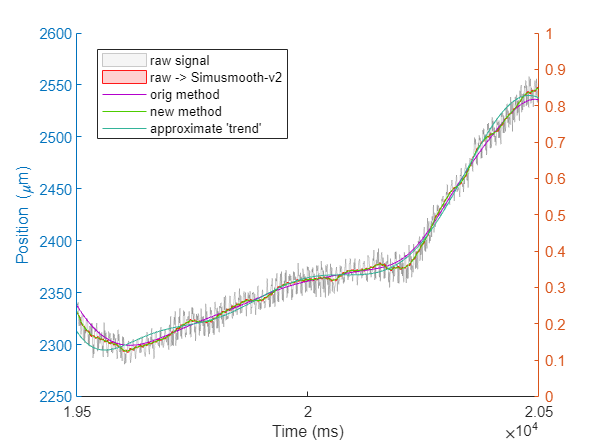

% Get signals
fakemovement_mm = 0.01*exp(times_ms/5000).*sin(times_ms*50/1000) * 0.05;
    fakemovement_v = gradient(fakemovement_mm, times_s);
    fakemovement_a = gradient(fakemovement_v, times_s); % ACTUAL acceleration

x_pos_raw = x_pos + fakemovement_mm*0;
filterwidth = 0.012;


% Filter attempts
        
        % ~~ POSITION FILTER 1 : S-G to remove noise, AND THEN filter out oscillations
            % with low-pass!
            % FILTER 0 : Emulating simulink model's filters (butter(6,0.6) -> mavge(10ms)),
            % to keep filter behaviour consistent between `mode_rawdata` settings
            if lower(mode_rawdata)=="raw"
                simulink_mavge_ms = 10;
                [bee,aye] = butter(6, 0.6);
                x_pos_simumean = movmean(filtfilt(bee,aye,x_pos_raw), simulink_mavge_ms);
            end
            % FILTER 1 : S-G -> moving average
            % noise_period_ms = 135;
            noise_period_ms = 135;
            % x_mavge = sgolayfilt(x_pos,1,noise_period_ms);
            x_sgfilt = sgolayfilt(x_pos_simumean,3,noise_period_ms);
            x_sgfilt2 = sgolayfilt(x_sgfilt,1,noise_period_ms);
            
            % FILTER 2 : Low-pass
            lowpass_cutoff_hz = filterwidth;
            filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
            [x_fil,~] = filter_lowpass(times_ms,x_sgfilt2,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');
        
            % FINAL FILTER:
            % Calculate accelerations real quicky-like (in mm/s/s)
            x_vel = gradient(x_fil, times_s);
            x_afil = gradient(x_vel, times_s);

% ~~ POSITION FILTER 2 : Experimental
    % FILTER 0 : Emulating simulink model's filters (butter(6,0.6) -> mavge(????ms)),
    % to keep filter behaviour consistent between `mode_rawdata` settings--
    % BUT choosing a frequency such that an obvious periodic trend is still
    % present
    if lower(mode_rawdata)=="raw"
        simulink_mavge_ms = 17;
        [bee,aye] = butter(6, 0.6);
        x_pos_simumean2 = movmean(filtfilt(bee,aye,x_pos_raw), simulink_mavge_ms);
        % Round off the remaining oscillations!
        noise_period_ms = 9;
        x_pos_simumean2 = sgolayfilt(x_pos_simumean2,2,noise_period_ms);
    end
    % FILTER 1 : S-G, mavge, etc
    % noise_period_ms = 13;
    % x_sgolay2 = sgolayfilt(x_pos_simumean2,2,noise_period_ms);

    % FILTER 2 : Low-pass (to find approximate trend that is 100% guaranteed real signal!)
    lowpass_cutoff_hz = 0.005;
    filtershape   = 5;        % Lower = more Gaussian, higher = more rectangular
    [x_trend,newfilt] = filter_lowpass(times_ms,x_pos_simumean2,0,lowpass_cutoff_hz,filtershape,1,'Low-pass');
    x_detrended = x_pos_simumean2 - x_trend;

    % FILTER 3 : S-G the detrended data
    noise_period_ms = 11;
    x_detrended_fil = sgolayfilt(x_detrended,1,noise_period_ms);
    % detrended_cutoff_hz = 0.000035;
    % x_detrended_fil = filter_lowpass(times_s,x_detrended,0,detrended_cutoff_hz,5,1,'Low-pass');
    x_processed = x_detrended_fil + x_trend;

    % FINAL FILTER:
    % Calculate accelerations real quicky-like (in mm/s/s)
    x_vel2 = gradient(x_processed, times_s);
    x_afil2 = gradient(x_vel2, times_s);


% ~~~~~~~~~~~~~~~~~~~Plot Position~~~~~~~~~~~~~~~~~~~~
    % Left axis: positions
figure;
yyaxis left
hold on
patchline(times_ms,(x_pos_raw)*1000, 'Color',[0, 0, 0, 0.2],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw signal');
% patchline(times_ms,(fakemovement_mm + mean(x_pos))*1000, 'Color',[0, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','--', 'DisplayName','true signal (only valid for stationary)');
patchline(times_ms,x_pos_simumean2*1000, 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth-v2');
plot(times_ms,x_fil*1000      , 'Color',[0.7, 0.0, 0.8, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','orig method');
plot(times_ms,x_processed*1000, 'Color',[0.3, 0.8, 0, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','new method');
plot(times_ms,x_trend*1000, 'Color',[0.2, 0.7, 0.6, 0.8],'LineWidth',0.1,'LineStyle','-', 'DisplayName',"approximate 'trend'");

% patchline(times_ms,(x_pos_raw-x_trend)*1000, 'Color',[0, 0, 0, 0.4],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw (detrended)');
% patchline(times_ms,(x_detrended)*1000, 'Color',[0, 0, 1, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth-v2 (detrended)');
% patchline(times_ms,(x_detrended_fil)*1000, 'Color',[0, 0.5, 0.5, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth-v2 -> fil (detrended)');
% scatter(times_ms, x_pos*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio')
hold off
ylabel("Position (\mum)")
xlabel("Time (ms)")
legend('Location','best')
% xlim([1.90e4,2.10e4]+2000)
% xlim([1.95e4,2.05e4]+2000)
% xlim([1.99e4,2.01e4]+2000)
xlim([1.95e4,2.05e4])

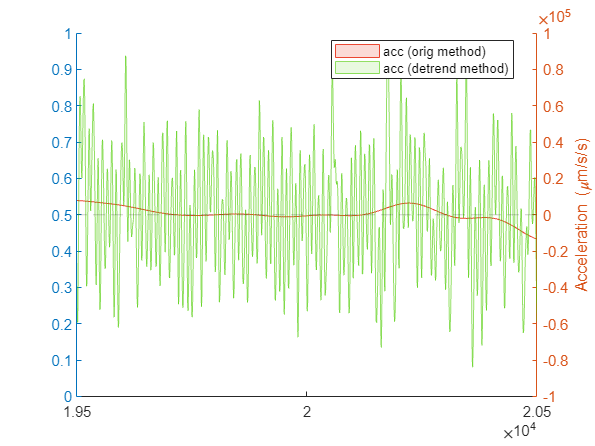


% ~~~~~~~~~~~~~~~~~~~Plot Accelerations~~~~~~~~~~~~~~~~~~~~~~~~~
% Left axis: positions
figure;

% Right axis: accelerations
yyaxis right
hold on
patchline(times_ms,x_afil*1000, 'Color',[0.9, 0.1, 0., 0.8],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc (orig method)');
patchline(times_ms,x_afil2*1000, 'Color',[0.3, 0.8, 0, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc (detrend method)');
% patchline(times_ms,x_afil_nodetrend*1000, 'Color',[0.1, 0.4,0.7, 0.9],'LineWidth',0.1,'LineStyle','--', 'DisplayName','acc (no detrend)');
% patchline(times_ms,x_afil2*1000, 'Color',[0.3, 0.8, 0, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','acc (detrended-fil)');
% patchline(times_ms,fakemovement_a*1000, 'Color',[0.2, 0.3, 0.8, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','ACTUAL accel.');
% scatter(times_ms, x_acc*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio','HandleVisibility','off')
patchline(times_ms,times_ms*0, 'Color',[0,0,0, 0.2],'LineWidth',0.5,'LineStyle','--', 'HandleVisibility','off');
hold off
legend("Location","best");
ylabel("Acceleration (\mum/s/s)")
% xlim([2.95e4,3.05e4])
% xlim([1.95e4,2.05e4]+2000)
% xlim([19600,19850]-1000)
xlim([1.95e4,2.05e4])


a = 6

a =      6